% Add nanobem simulation library
addpath(genpath("C:\Users\ngraf\Downloads\uhohenester-nanobem22-3347be6"));

Error using publish
Unable to publish "nanobem_base.m". Using the publish function to publish a MATLAB code file (.m) from a live script or function is not supported.

Error in makehelp (line 13)
  publish( files( i ).name, struct( 'evalCode', false ) );

%% ========================================================================
%  Build populations of LNP particles (full, empty, blebbed) for nanobem
%  ========================================================================
%  NOTE: Material(eps, mu) takes PERMITTIVITY, not refractive index.
%  For a non-dispersive dielectric, eps = n^2 (mu = 1). This is why the
%  doc example Material(2.25,1) corresponds to n = 1.5, not n = 2.25.

% addpath(genpath(nanobemdir));   % make sure nanobem is on the path

nverts = 144;   % trisphere discretization -- bump this up for larger
                % particles / higher index contrast, same convergence
                % logic as for any BEM/DDA mesh: refine until cross
                % sections stop changing.

%% ---- background medium (aqueous buffer surrounding the LNPs) ----
n_medium   = 1.335;
mat_medium = Material(n_medium^2, 1);

%% ========================================================================
%  1) FULL LNPs (mRNA-loaded)
%     size range: 99 +/- 46 nm diameter (Leslie & Cullis)
%     RI = 1.515
%  ========================================================================
n_full   = 1.515;
mat_full = Material(n_full^2, 1);
mat_set_full = [mat_medium, mat_full];     % 1 = background, 2 = particle

N_full      = 20;      % number of particles to build for this population
d_mean_full = 99;       % nm
d_sd_full   = 46;       % nm

full_lnp = cell(N_full, 1);
for k = 1:N_full
    d = -1;
    while d <= 0                     % reject non-physical draws from the normal tail
        d = d_mean_full + d_sd_full * randn;
    end
    p   = trisphere(nverts, d);
    tau = BoundaryEdge(mat_set_full, p, [2, 1]);   % LNP material inside, medium outside
    full_lnp{k} = struct('tau', tau, 'diameter', d);
end

%% ========================================================================
%  2) EMPTY LNPs
%     size range: 79 +/- 32 nm diameter (Leslie & Cullis)
%     RI = 1.42
%  ========================================================================
n_empty   = 1.42;
mat_empty = Material(n_empty^2, 1);
mat_set_empty = [mat_medium, mat_empty];

N_empty      = 20;
d_mean_empty = 79;
d_sd_empty   = 32;

empty_lnp = cell(N_empty, 1);
for k = 1:N_empty
    d = -1;
    while d <= 0
        d = d_mean_empty + d_sd_empty * randn;
    end
    p   = trisphere(nverts, d);
    tau = BoundaryEdge(mat_set_empty, p, [2, 1]);
    empty_lnp{k} = struct('tau', tau, 'diameter', d);
end


%% ========================================================================
%  3) BLEBBED LNPs
%     Modeled as a full lipid core + an adjoining aqueous bleb -- i.e. two
%     separate closed spheres in contact, each homogeneous, rather than one
%     fused two-material body sharing an internal partition. See note in
%     the chat response for why: a truly fused, single-envelope bleb needs
%     a conformal 3-material surface mesh nanobem has no built-in tool to
%     generate, whereas two touching spheres is an ordinary multi-particle
%     BEM setup.
%
%     lipid core:   RI = 1.495 (full lipid, Leslie & Cullis)
%     aqueous bleb: RI = 1.45  (placeholder, similar to an mRNA-loaded
%                               unilamellar vesicle / EV -- adjust as you
%                               refine this estimate)
%  ========================================================================
n_lipid   = 1.495;
n_aqueous = 1.45;
mat_lipid   = Material(n_lipid^2, 1);
mat_aqueous = Material(n_aqueous^2, 1);

% one material list covering all three media in this system
mat_set_bleb = [mat_medium, mat_lipid, mat_aqueous];   % 1=medium, 2=lipid, 3=aqueous

N_bleb = 20;

% core (lipid) and bleb (aqueous) diameters -- placeholders, tune to your
% actual morphology data. Core reuses the "full" LNP size range; bleb size
% and neck geometry are the two things most worth revisiting.
d_mean_core = 99;  d_sd_core = 46;
d_mean_bleb = 40;  d_sd_bleb = 15;
neck_overlap = 5;   % nm the two spheres are pushed together at the neck

blebbed_lnp = cell(N_bleb, 1);
for k = 1:N_bleb
    d_core = -1; while d_core <= 0, d_core = d_mean_core + d_sd_core * randn; end
    d_bleb = -1; while d_bleb <= 0, d_bleb = d_mean_bleb + d_sd_bleb * randn; end

    p_core = trisphere(nverts, d_core);
    p_bleb = trisphere(nverts, d_bleb);

    % Shift the bleb sphere so it sits just touching (or slightly
    % overlapping, at the neck) the core sphere along x.
    % `shift` is documented for the 2D `polygon` class; if your nanobem
    % version's 3D particle object doesn't expose an equivalent method,
    % translate the vertices directly instead, e.g.:
    %   p_bleb.verts(:,1) = p_bleb.verts(:,1) + center_dist;
    center_dist = d_core/2 + d_bleb/2 - neck_overlap;
    p_bleb = shift(p_bleb, [center_dist, 0, 0]);

    tau_core = BoundaryEdge(mat_set_bleb, p_core, [2, 1]);   % lipid inside, medium outside
    tau_bleb = BoundaryEdge(mat_set_bleb, p_bleb, [3, 1]);   % aqueous inside, medium outside

    blebbed_lnp{k} = struct('tau_core', tau_core, 'tau_bleb', tau_bleb, ...
                             'd_core', d_core, 'd_bleb', d_bleb);
end

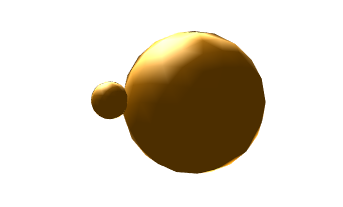

% Plot the lnps to do quality control
% Blebbed LNPs are a great simplification of the real structure, more
% accurate modelling would require different mesh approach
tau1 = blebbed_lnp{3,1}.tau_core;
tau2 = blebbed_lnp{3,1}.tau_bleb;

figure;
plot(tau1);
plot(tau2);
axis equal; grid on; camlight;

% Simulate and create PSFs for all of the particles before
%  initialize BEM solver
rules = quadboundary.rules( 'quad3', triquad( 1 ) );
bem = galerkin.bemsolver( tau, 'rules', rules );
%  planewave excitation
exc = galerkin.planewave( [ 1, 0, 0 ], [ 0, 0, 1 ] );

%  wavelength of light in vacuum
lambda = 555;
%  toolbox internally uses wavenumber of light in vacuum
k0 = 2 * pi / lambda;
%  plane wave excitation
q = exc( tau, k0 );
%  solve BEM equations
sol = bem \ q

sol =   solution with properties:

    tau: [1×284 BoundaryEdge]
     k0: 0.0113
      e: [426×1 double]
      h: [426×1 double]


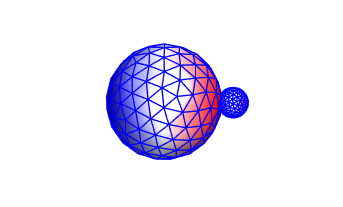

%  surface charge distribution
sig = surfc( sol );
%  plot surface charge distribution
plot( tau2, sig, 'EdgeColor', 'b' );
colormap( redblue );

% Store all of those PSFs for 